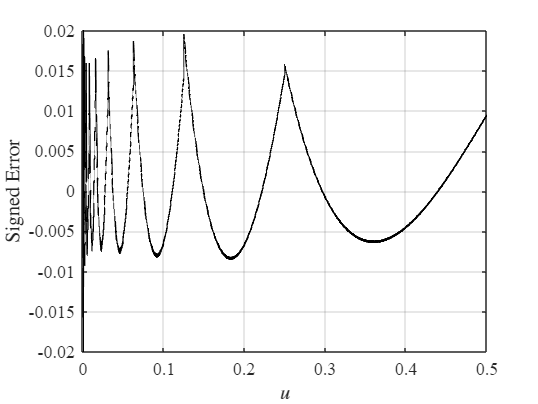

%% Method 2: Piecewise Linear Approximation on Dyadic Intervals

clear; clc;

d              = 14;                           
Nhalf          = 2^(d-1);                     
u_edges        = (0:Nhalf)/2^d;               
nSamplesPerBin = 50;                          
delta          = 1e-12;                       
du             = 2^(-d);

Z_ave  = arrayfun(@(u1,u2) norminv_int(u1,u2)/du, u_edges(1:end-1), u_edges(2:end));
Z2_ave = arrayfun(@(u1,u2) norminv2_int(u1,u2)/du, u_edges(1:end-1), u_edges(2:end));

Z2 = Z_ave; 

% Linear fit
for k = 1:d-1
    if k==1 
      n_sub = 2;
      k2 = 1:2;
    else
      n_sub = 2^(k-1);
      k2 = (n_sub+1):2*n_sub;
    end
    Z_ave2 = sum(Z_ave(k2))/n_sub;
    dn = (1:n_sub) - (n_sub+1)/2;
    dZ = Z_ave(k2) - Z_ave2;
    dZ = (dZ*dn') / (dn*dn');
    Z2(k2) = Z_ave2 + dn*dZ;
end

all_u    = [];
all_err  = [];
maxErr   = zeros(1, Nhalf);

for j = 1:Nhalf
    uL = u_edges(j)   + delta;
    uR = u_edges(j+1) - delta;
    us = linspace(uL, uR, nSamplesPerBin);
    qs = sqrt(2)*erfinv(2*us - 1);    % true Phi^{-1}(u)

    errs = Z2(j) - qs;

    all_u   = [all_u,   us];
    all_err = [all_err, errs];

    maxErr(j)   = max(abs(errs));
end

maxZ         = max(abs(Z2));
u_mid = (u_edges(1:end-1) + u_edges(2:end))/2;

theoretical_MSE = mean(Z2_ave - 2*Z2.*Z_ave + Z2.^2);


% Signed Error Plot
figure;
plot(all_u, all_err, 'k', 'LineWidth', 1.2);
xlabel('$u$', 'Interpreter', 'latex');   % Italic math font
ylabel('Signed Error', 'Interpreter', 'latex');
ylim([-0.02, 0.02]);
grid on;
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman');

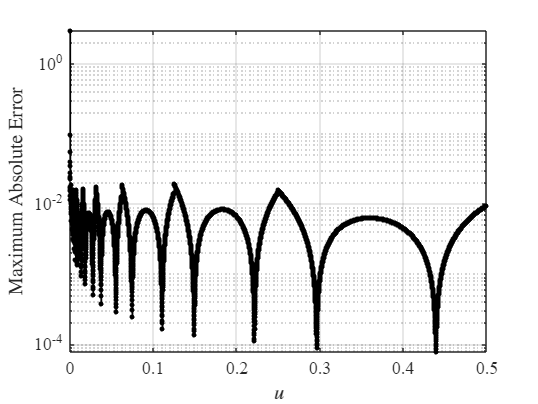

set(gcf, 'Color', 'w');

% Max Absolute Error Plot
figure;
semilogy(u_mid, maxErr, 'k.-', 'LineWidth', 1.2, 'MarkerSize', 10);
xlabel('$u$', 'Interpreter', 'latex');   % Italic math font
ylabel('Maximum Absolute Error', 'Interpreter', 'latex');
grid on;
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman');

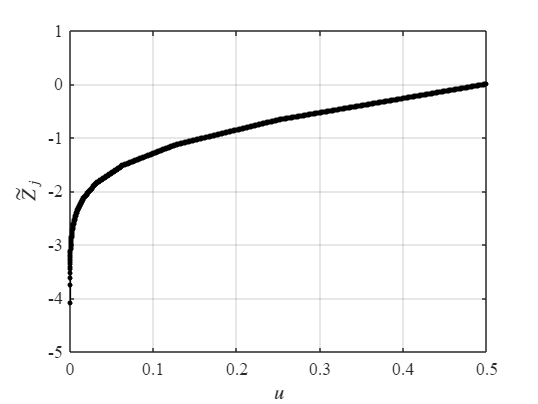

set(gcf, 'Color', 'w');

% LUT Approximation
figure;
plot(u_mid, Z2, 'k.-', 'LineWidth', 1.2, 'MarkerSize', 10);
xlabel('$u$', 'Interpreter', 'latex');   % Italic math font
ylabel('$\tilde Z_j$', 'Interpreter', 'latex');
grid on;
set(gca, 'FontSize', 12, 'FontName', 'Times New Roman');

set(gcf, 'Color', 'w');


fprintf('d: %d\n', d);

d: 14


fprintf('MSE over [0,0.5]: %.3e\n', theoretical_MSE);

MSE over [0,0.5]: 4.806e-05


fprintf('Maximum absolute LUT value: %.6f\n', maxZ);

Maximum absolute LUT value: 4.075145


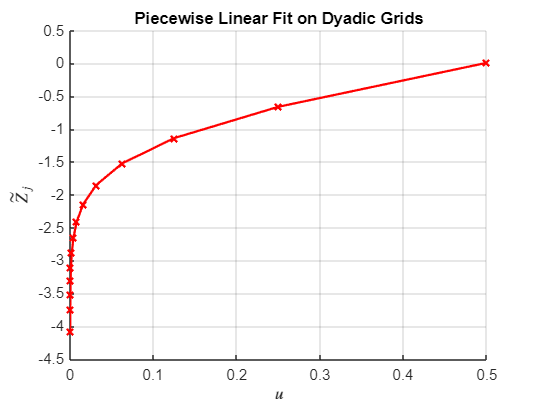



%% Obtaining LUT Array: Optimal coefficeints (a,b)
d=14;
idx = d:-1:1;
grid_idx =2^d*2.^(-idx);
dyadic_points=2.^(-idx);

grid_vals = Z2(grid_idx);

delta_x = diff(dyadic_points);
delta_y = diff(grid_vals);         
b = delta_y ./ delta_x;           
a = grid_vals(1:end-1) - b .* dyadic_points(1:end-1);  

LUT = [a(:), b(:)];

figure
title('Piecewise Linear Fit on Dyadic Grids')
xlabel('$u$', 'Interpreter', 'latex');   
ylabel('$\tilde Z_j$', 'Interpreter', 'latex');
grid on
hold on
for i = 1:length(b)
    xx = linspace(dyadic_points(i), dyadic_points(i+1), 2);
    yy = a(i) + b(i)*xx;
    plot(xx, yy, '-xr', 'LineWidth', 1.5);
end



%%Saving as a cpp array (.h file)
headerFile = 'dyadic_lut_26.h';
fid = fopen(headerFile,'w');

fprintf(fid, '// dyadic_lut_26.h\n');
fprintf(fid, '#pragma once\n\n');

%FP32
fprintf(fid, 'inline constexpr float DYADIC_LUT_A_FP32[13] = { ');
for i=1:13
    fprintf(fid, '%0.8gf', a(i));
    if i<13, fprintf(fid, ', '); end
end
fprintf(fid, ' };\n');
fprintf(fid, 'inline constexpr float DYADIC_LUT_B_FP32[13] = { ');
for i=1:13
    fprintf(fid, '%0.8gf', b(i));
    if i<13, fprintf(fid, ', '); end
end
fprintf(fid, ' };\n\n');

% FP16
fprintf(fid, 'inline constexpr _Float16 DYADIC_LUT_A_FP16[13] = { ');
for i=1:13
    fprintf(fid, '%g', a(i));
    if i<13, fprintf(fid, ', '); end
end
fprintf(fid, ' };\n');
fprintf(fid, 'inline constexpr _Float16 DYADIC_LUT_B_FP16[13] = { ');
for i=1:13
    fprintf(fid, '%g', b(i));
    if i<13, fprintf(fid, ', '); end
end
fprintf(fid, ' };\n\n');

fprintf(fid, '// Dyadic interval endpoints on [0, 0.5]\n');
fprintf(fid, 'static constexpr float DYADIC_U[%d] = { ', numel(dyadic_points));
fprintf(fid, '%.8gf, ', dyadic_points);   % prints each value with an 'f' suffix
fprintf(fid, '};\n');


fclose(fid);



% Local Functions 
function y = norminv_int(u1, u2)
    u1 = max(u1,1e-15);
    u2 = min(u2,1-1e-15);
    z1 = sqrt(2) * erfinv(2*u1 - 1);
    z2 = sqrt(2) * erfinv(2*u2 - 1);
    y  = normpdf(z1) - normpdf(z2);
end

function y = norminv2_int(u1, u2)
    u1 = max(u1,1e-15);
    u2 = min(u2,1-1e-15);
    z1 = sqrt(2) * erfinv(2*u1 - 1);
    z2 = sqrt(2) * erfinv(2*u2 - 1);
    y  = z1.*normpdf(z1) - z2.*normpdf(z2) + (u2-u1);
end